% define superclusters based on the clustering results
% Author: Chang Lu
% luchang4104@gmail.com

clear all

% you can put your data folder under 'data' 
currentFolder = pwd;

% datapath = [currentFolder,filesep,'data',filesep,'mix with cd163'];
% or set you own path( replace the sentence above to the example below):
% datapath = '/Users/changlu/DATA/OLIVIA/30 clusters CDK5 New'; % your own data path
% datapath = '/Users/changlu/DATA/Elias/data';
datapath = '/Volumes/ChangLu/Laura/LK7newfoldersforchang';
addpath(genpath('fun'));


files=dir(fullfile(datapath));
isub = [files(:).isdir];
fileNames={files(isub).name}';
fileNames(ismember(fileNames,{'.','..','results'})) = [];


##  load data

% the mat files in the datapath
clusterfilename = 'cosine_kmedoids_k=40';
datamatname = 'cellmarker_rescale_intergration_t=2';

load([datapath,filesep,clusterfilename]); % clustering results
load([datapath,filesep, datamatname]);

%h = draw_mst_new(labels,centers,'cosine',[],'T');
% print(gcf,'-dpng',[directory,'MST.jpg']);

## result save path

directory = [datapath,filesep,'results',filesep, datamatname, clusterfilename,filesep];
if ~exist(directory,'dir')
    mkdir(directory);
end


## supercolors

%supercolors = flipud(jet(length(unique(superlabels))));
% the maximun number of superclusters is 25. do not change it.
supercolors = [219,69,50;
106,213,75;
113,68,204;
190,218,75;
204,72,193;
123,213,137;
73,39,112;
228,194,68;
100,123,204;
217,130,69;
108,216,195;
218,71,119;
79,131,62;
198,131,203;
170,150,67;
143,55,102;
205,206,163;
78,36,42;
177,181,215;
145,63,44;
94,159,169;
201,137,145;
50,71,48;
68,72,99;
120,103,63];
supercolors = supercolors./255;

## define super clusters by yourself

superlabels = insertBefore(string(labels),1,"C-"); % do not modify this raw

% you can adjust to your superclusters below
superlabels(labels == 20 | labels == 3) = "SC-1";
superlabels(labels == 4 | labels == 7 | labels == 15 | labels == 29 | labels == 38| labels == 40) = "SC-2";
superlabels(labels == 13 | labels == 35)= "SC-3";
superlabels(labels == 37 | labels == 12 | labels == 19| labels == 26) = "SC-4";
superlabels(labels == 1 | labels == 5 | labels == 17| labels == 24 | labels == 34 | labels == 39) = "SC-5";
superlabels(labels == 2 | labels == 30 | labels == 33) = "SC-6";
superlabels(labels == 9 | labels == 21) = "SC-7";

uni_labels = unique(unique(superlabels));
COLORT = table(supercolors(1:length(uni_labels),:),uni_labels);
COLORT.Properties.VariableNames{'uni_labels'} = 'superlabels';
COLORT.Properties.VariableNames{'Var1'} = 'supercolors';
bindtable = unique(table(labels, superlabels),'rows');
TT = join(bindtable,COLORT,'Keys','superlabels');

%save superclusters colors to csv file
% here change to your own file name
writetable(TT,[datapath,filesep, 'rescale_t=2_supercluster.csv']) 

## visualize super cluster on MST

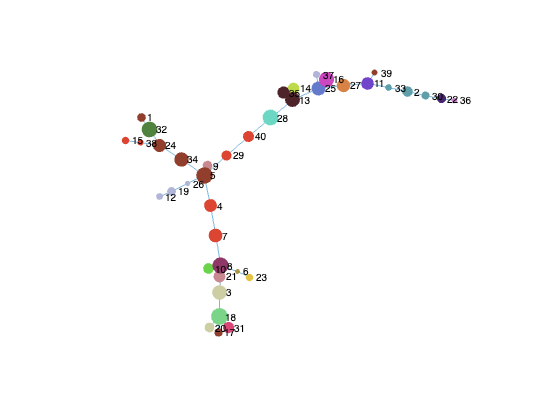

h = draw_mst_new(labels,centers,'cosine',TT.supercolors, 'F');

% you can change the filename below if you want
print(gcf,'-dpng',[directory,'SuperClu-MST17.jpg']);